# Lecture 5 Geometric Imaging

## 1. Ideal lens imaging

### 1.1 Ray tracing for ideal lens

In the case of an ideal lens, tracing two special types of rays as they pass through the lens can help us trace any ray. These two types of rays are:

***Parallel ray, ***starts from a point on the object that parallel to the optical axis. The refracted ray or its extension intersects with the focal point. 

***Focal ray, ***starts at the same point on the object and travels through the center of the lens, then continues on the other side of the lens parallel to the principal axis.

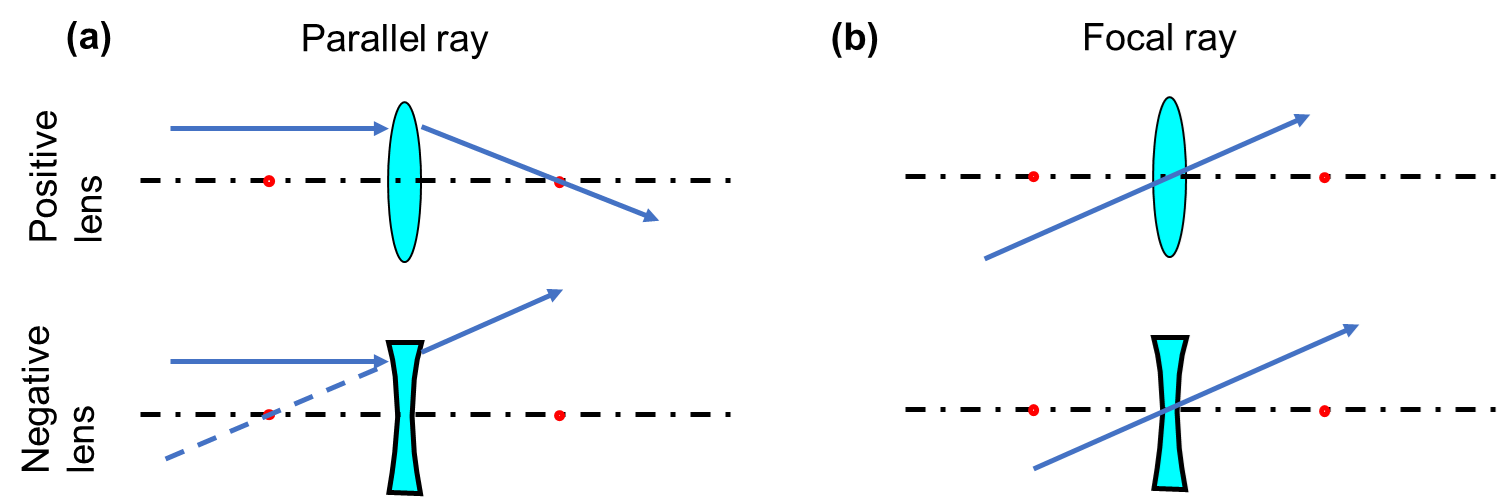

**ILL. 1.1 ***Ray tracing for ideal lens*

### **1.2 Newton's imaging equation**

Imaging Equation


$$\frac{1}{d_1 }+\frac{1}{d_2 }=\frac{1}{f}$$


$f$ is the focal length. If $f>0$ the lens is convex (positive lens) and if $f<0$ the lens is concave (negative)

$d_1$ is the distance from the lens to the focal plane; $d_1 >0$ if the object is on the left of the optical axis.

$d_2$ is the distance from the lens to the image plane; $d_2 >0$ if the image is on the right of the optical axis.

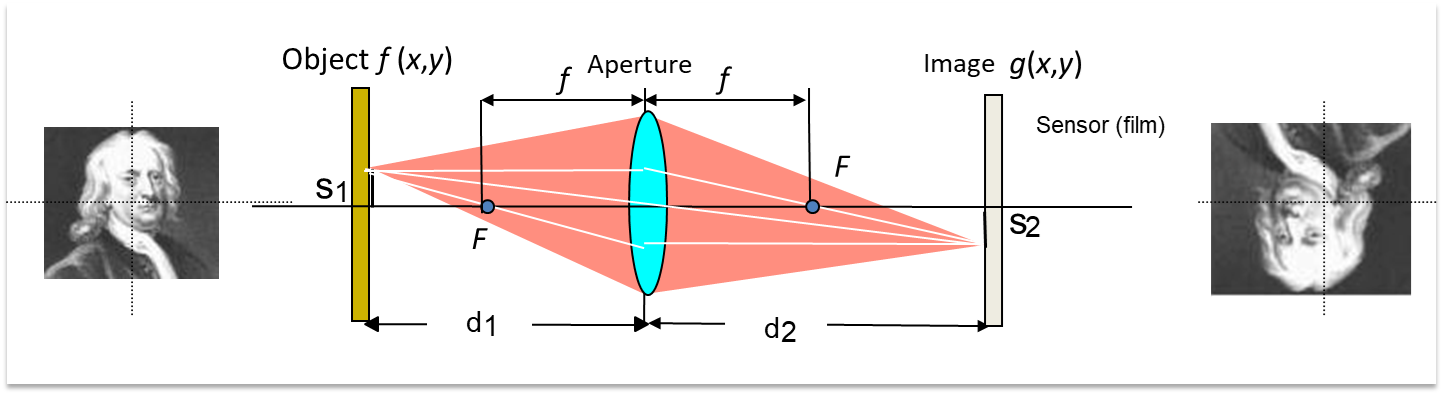

**ILL. 1.2 ***Newton's equation for geometrics imaging*

### **1.3 Magnification**

Magnification, $M=-\frac{S_2 }{S_1 }=-\frac{d_2 }{d_1 }$

$M<-1$, image size is larger than the object size (magnification). The object distance $d_1$ satisfies $f<d_1 <2f$.

$-1\le M<0$, image size is smaller than the object size (minification). The object distance $d_1$ satisfies $d_1 >2f$.

A perfectly focused system introduces only a geometric transformation (magnification/minification)

              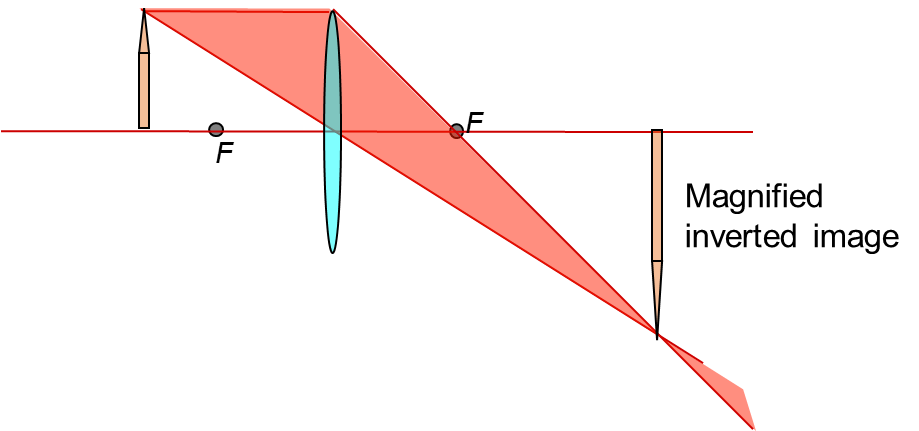

**ILL. 1.3** *Magnified inverted image*

      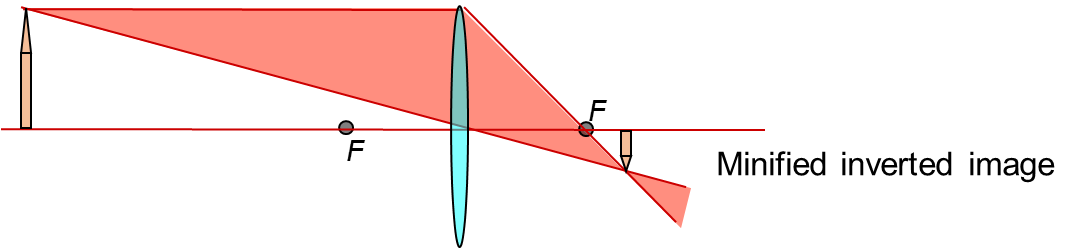

**ILL 1.4 ***Minified inverted image*

### 1.4 Virtual image

$M=+\infty$, when object reaches the focal plane, $d_1 =f$, the image is at infinity.

           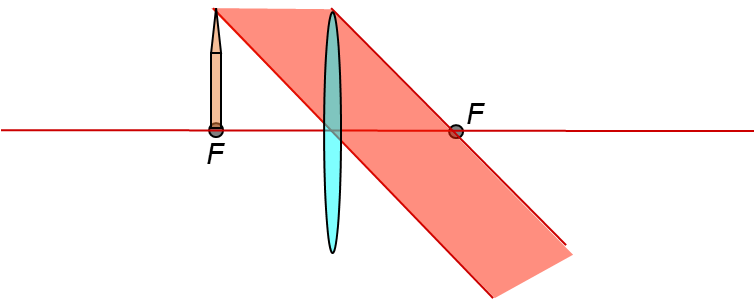

**ILL. 1.5** *Image forming at infinity*

$M>1$, image size is larger than the object size (magnification). The object distance $d_1$ satisfies $0<d_1 <f$. The image distance $d_2 <0$.

    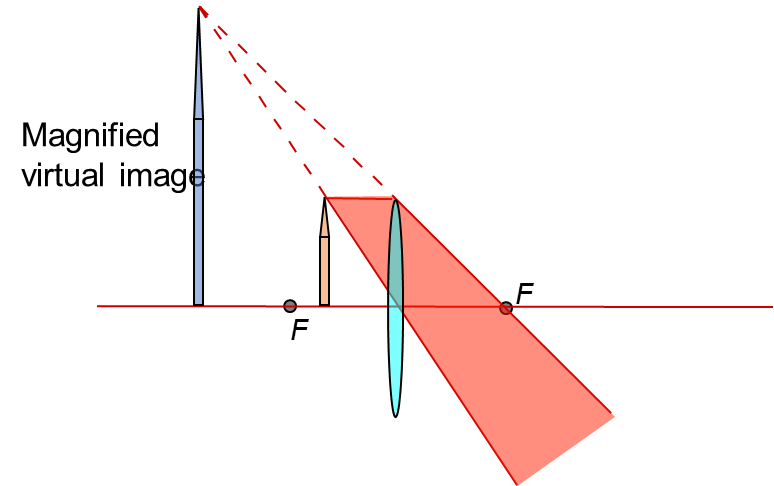

**ILL. 1.6 ***Magnified virtual image*

***Example 1.1***

Demonstration of Newton's imaging equation.

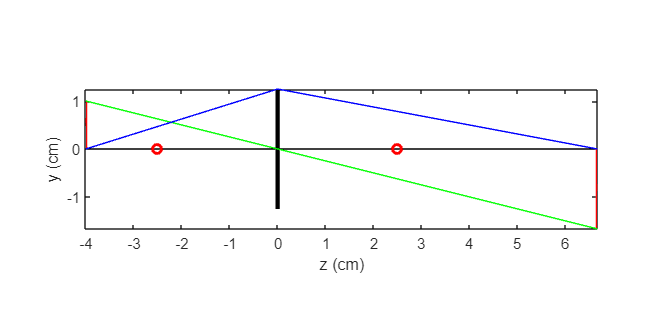

% unit cm
f = 2.5; % positive lens
aper = 1.25; % radius of the aperture
d1 =4;
s1 = 1; % height of the object
d2 = d1*f/(d1-f);
mag = -d2/d1;
s2 = mag*s1; % height of the image

% plot the geometric imaging schematics
figure()
geo_plot1(d1,s1,d2,s2,f,aper)
set(gcf,'Position', [100 100 600 300])

*Notes:* 

- *The source code for *`geo_plot1`* is attached in the **Appendix.*

- *The green line represents the chief ray and the blue line is the marginal ray. Dashed line indicates back extension of a ray*

## 2. Defocused geometric system

### 2.1 Geometrical defocusing

Let's assume that the original object distance is $d_{10}$ and the image distance is $d_2$.

If we introduce defocusing on the object side, the new object distance becomes $d_1$.

The new image distance is $d_{20}$. The blurring will be observed on the original image plane, at distance $d_2$. 

The light cone can be observed with its apex at $d_{20}$ and the base plane located at $d_2$. The blurring is a circle. 

The point spread function is therefore a cylindrical function with diameter $D_s$. $D_s$ is not only determined by the amount of defocusing, but also by the aperture of the lens $D$.a

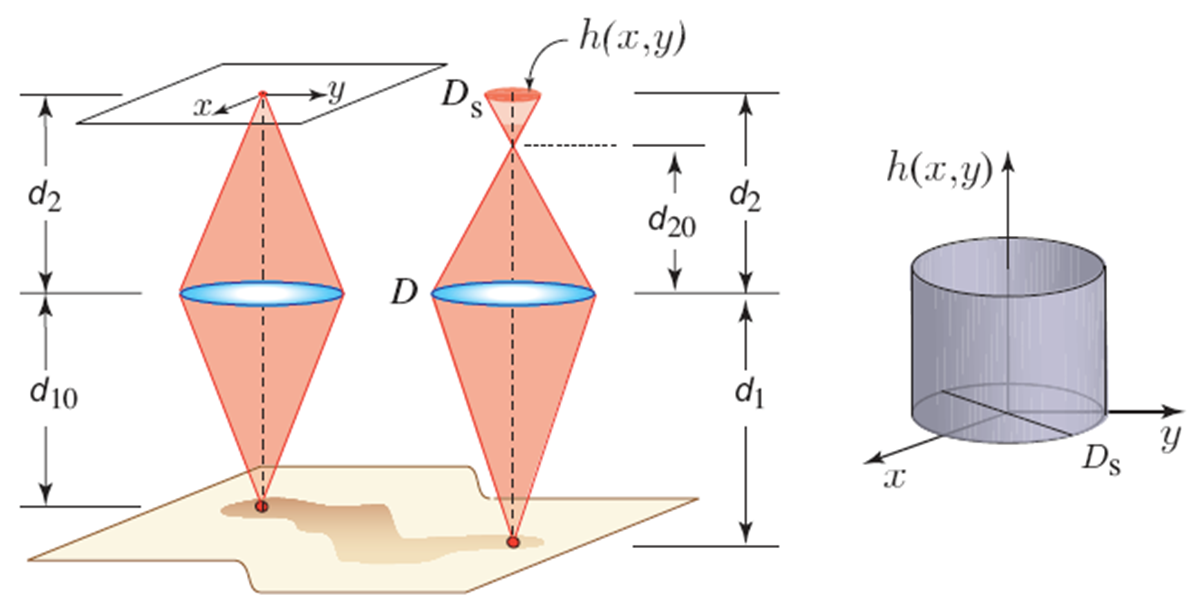

**ILL 2.1 ***Defocusing in geometrics optics regime*

To derive the defocusing PSF diiameter $D_s$, we notice the geometric relation between $D_s$ and the aperture of the lens $D$.


$$D_s =\frac{d_2 -d_{20} }{d_{20} }D$$
 

We also know from Newton's equation that an object located at $d_1$ forms an image $d_{20}$.


$$\frac{1}{d_{20} }=\frac{1}{f}-\frac{1}{d_1 }$$


If we subract $\frac{1}{d_2 }$ on both sides of the equation, we get


$$\frac{1}{d_{20} }-\frac{1}{d_2 }=\frac{d_2 -d_{20} }{d_{20} d_2 }$$



$$=\frac{1}{f}-\frac{1}{d_1 }-\frac{1}{d_2 }$$


If we define $\frac{1}{d_e }=\frac{1}{f}-\frac{1}{d_1 }-\frac{1}{d_2 }$, then $\frac{d_2 -d_{20} }{d_{20} }=\frac{d_2 }{d_e }$


$$D_s =\frac{d_e }{d_2 }D$$


***Example 2.1***

Calculate the defocus diameter.

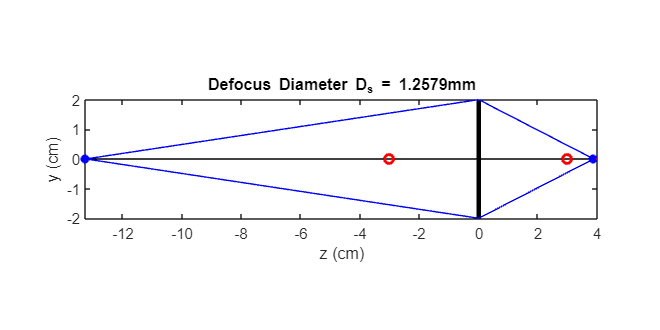

%unit cm
f = 3; % positive lens
aper = 2; % radius of the aperture
d1 = 13.25; % object distance
d2 = 4; % original object distance
d20 = f*d1/(d1-f); % new object distance
inv_de = 1/f -1/d1-1/d2; 
rs = inv_de*d2*aper;
Ds = abs(rs*2*10);

% plot the geometric imaging schematics
figure()
geo_plot2(f,aper,d1,d2,d20,rs,Ds)
set(gcf,'Position', [100 100 600 300])

*Notes:* 

- *The source code for *`geo_plot2`* is attached in the **Appendix.*

### 2.2 Optical transfer function for geometrical defocused system

The PSF of a defocused ideal lens system is a cylindrical function with diameter $D_s$. The cylinder function is defined as:


$$h\left(x,y\right)=\left\lbrace \begin{array}{ll}
1, & x^2 +y^2 \le \frac{D_s^2 }{4}\\
0, & x^2 +y^2 >\frac{D_s^2 }{4}
\end{array}\right.$$


The optical transfer function (OTF) of a defocused imaging system is Sombrero function.


$$H\left(k=\sqrt{k_x^2 +k_y^2 }\right)=\frac{\pi D_s^2 }{2}\cdot \frac{J_1 \left(\frac{{\textrm{kD}}_s }{2}\right)}{\left(\frac{{\textrm{kD}}_s }{2}\right)}$$


$J_s$ is a Bessel function of the first kind, with order 1.

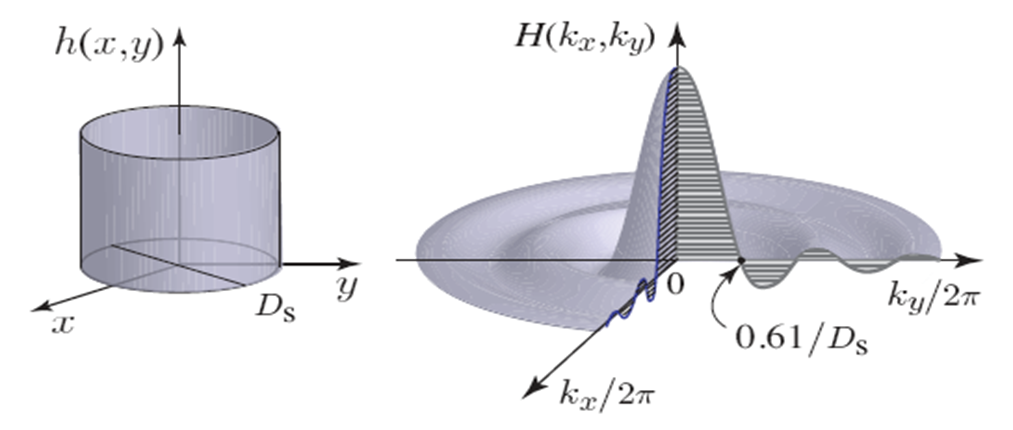

**ILL 2.2 **PSF and OTF of defocused ideal lens system

***Example 2.2***

Fourier transform of cylinder function.

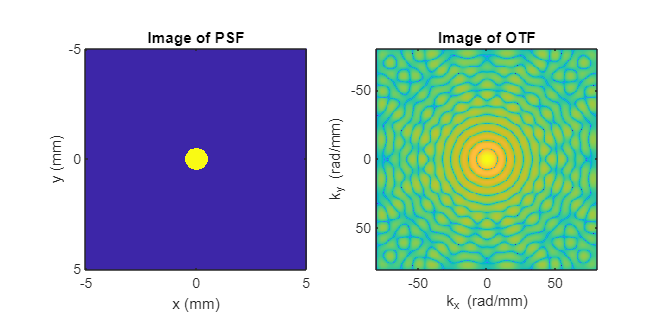

n=256;
x = linspace(-5,5,n); % unit mm.
dx = x(2)-x(1);
y = linspace(-5,5,n); 
[X,Y]=ndgrid(x,y);

Ds = 1; % PSF diameter
h = zeros(n);
h(X.^2+Y.^2<(Ds/2)^2)=1;

h_hat=fftshift(fft2(h)); % optical transfer function
k=pi/dx*linspace(-1,1,n); % wavenumber unit rad/mm

% Numerical 
figure()
%PSF
subplot(121)
imagesc(x,y,h)
axis image;
title('Image of PSF')
xlabel('x (mm)')
ylabel('y (mm)')

% OTF
subplot(122) 
imagesc(k, k, log(abs(h_hat)))
axis image
title('Image of OTF')
xlabel('k_x (rad/mm)')
ylabel('k_y (rad/mm)')

set(gcf, 'Position', [100 100 600 300])

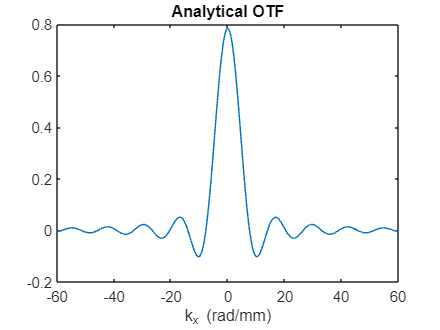

% analytical OTF
figure()
H = Ds.^2*pi*besselj(1,k*Ds/2)./k;
plot(k,H)
title('Analytical OTF')
xlabel('k_x (rad/mm)')
xlim([-60,60])

set(gcf, 'Position', [100 100 400 300])

## 3. Appendix: Helper functions

### `geo_plot1` 

`Plots the image in ``Example 1.1`` according to Newton equation.`

function geo_plot1(d1,s1,d2,s2,f,aper)
% d1, s1 are the location and height of the object, respectively.
% d2, s2 are the location and height of the image, respectively.
% f is the focal length, aper is the half diameter of the aperture.

    % lens
    plot([0,0], [-aper,aper], 'k', 'LineWidth', 3); % lens
    hold on;
    % z axis
    plot([-d1,0], [0,0], 'k', 'LineWidth', 1);
    plot([0,d2], [0,0], 'k', 'LineWidth', 1);
    % foci
    plot([-f,f], [0,0], 'ro', 'LineWidth', 2);
    % object
    plot([-d1,-d1], [0, s1], 'r','LineWidth', 2);
    % image
    plot([d2,d2], [0, s2], 'r','LineWidth', 2);
    % chief ray
    plot([-d1,0],[s1,0], 'g');
    if d2 == inf % infinity
        plot([0, f], [0, -s1], 'g')
    elseif d2 > 0
        plot([0,d2],[0,s2], 'g');
    else  % virtual image
        plot([0,d2],[0,s2], 'g--');
    end
    % marginal ray
    plot([-d1,0],[0,aper], 'b');
    if d2 == inf % infinity
        plot([0, f], [aper, aper], 'b')
    elseif d2 > 0
        plot([0, d2],[aper, 0], 'b');
    else % virtual image
        plot([0, d2],[aper, 0], 'b--');
    end
    axis image;
    xlabel('z (cm)')
    ylabel('y (cm)')
    hold off
end

### `geo_plot2`

`Plots the image of the defocusd system in ``Example 2.1.`

function geo_plot2(f,aper,d1,d2,d20,rs,Ds)
% f is the focal length
% aper is the half diameter of the aperture
% d1 and d2 are the object and original image distance, respectively
% d20 is the new object distance
% rs is the radius of defocus in cm
% Ds is the diameter of defocus in mm

    % lens
    plot([0,0], [-aper,aper], 'k', 'LineWidth', 3);
    hold on;
    % z axis
    plot([-d1,0], [0,0], 'k', 'LineWidth', 1); 
    plot([0,d2], [0,0], 'k', 'LineWidth', 1); 
    % foci
    plot([-f,f], [0,0], 'ro', 'LineWidth', 2); 
    % object and image
    plot([-d1,d20], [0, 0], 'b*','LineWidth', 2);
    % image plane
    plot([d2,d2], [-rs, rs], 'r','LineWidth', 2);
    % marginal ray
    plot([-d1,0],[0,aper], 'b'); 
    plot([0, d2],[aper, -rs], 'b');
    plot([-d1,0],[0,-aper], 'b'); 
    plot([0, d2],[-aper, rs], 'b');
    axis image;
    xlabel('z (cm)')
    ylabel('y (cm)')
    if d1 == f %d2 at infinity
    title('Image is at infinity, Defocus Diameter D_s = N/A');
    else
    title(['Defocus Diameter D_s = ', num2str(Ds), 'mm']);
    end
    hold off

end